# Válogatott modellek a matematikai biológiában

# 2. gyakorlat

### Diffúzió egyenlet megoldása Dirichlet, Neumann és periodikus peremfeltételek mellett

Időbeli ($\tau$) ill. térbeli $(h)$ lépésközök megválasztása:

dt = logspace(-3,0,150);
dx = 1;

Időhorizont amelyen vizsgálom a dinamikát (mintavételi pontok száma): 

T = 50;
nT = round(T ./ dt)

nT =        50000       47735       45572       43508       41537       39655       37859       36144       34506       32943       31451       30026       28665       27367       26127       24943       23813       22735       21705       20721       19783       18886       18031       17214       16434       15690       14979       14300       13652       13034       12444       11880       11342       10828       10337        9869        9422        8995        8588        8199        7827        7473        7134        6811        6502        6208        5926        5658        5402        5157


T_act = nT .* dt;

Kémcső / rúd / ált. közeg hossza:

L = 200;
nL = L / dx;

Diffúzió sebessége:

D = 1;

A diszkretizációt követően az egyenletben szereplő $\mu = D \frac{\tau}{h^2}$ értéke:

mu = D*dt/dx^2;

Emlékezzünk, a diszkretizáció eredménye:


$$u_{i+1,j} = u_{i,j-1} + (1-2\mu) u_{i,j} + u_{i,j+1}$$


Vizsgált pontok a térdimenzió mentén, illetve a vizsgált pontok száma:

x = 1:dx:L;
nx = length(x);

A teljes $u(t,x)$ függvény numerikus közelítésének mátrix alakja, $U = \big(u_{i,j}\big)_{i=1,\dots,n_t,\,j=1,\dots,n_x}$

U = zeros(nx,nt);

Lehetséges kezdeti feltételek

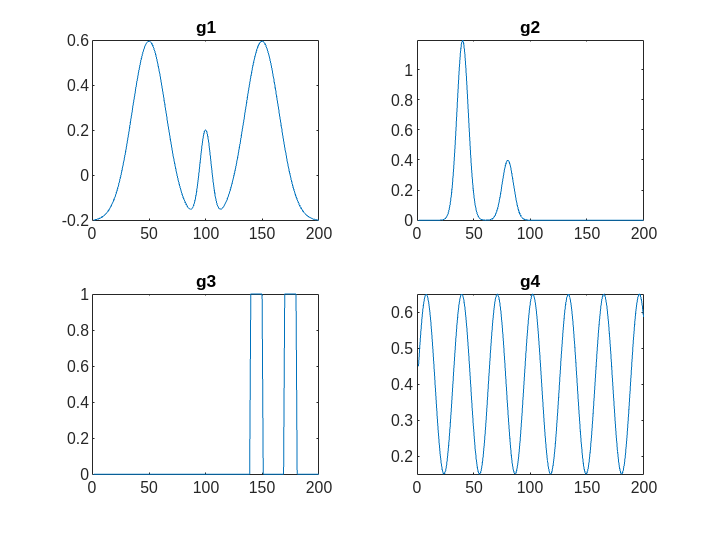

g1 = normpdf(x,L/4,15)*30 + normpdf(x,L/2,5)*5 + normpdf(x,3*L/4,15)*30;
g1 = g1 - min(g1) - 0.2;

g2 = normpdf(x,1*L/5,5)*15 + normpdf(x,2*L/5,5)*5;
g2 = g2 - min(g2);

g3 = zeros(nx,1);
g3(170:180) = 1;
g3(140:150) = 1;

g4 = 0.4+sin(1/5*x)/4;

fig = figure(1);
delete(fig.Children)
nexttile; plot(x,g1); title g1
nexttile; plot(x,g2); title g2
nexttile; plot(x,g3); title g3
nexttile; plot(x,g4); title g4

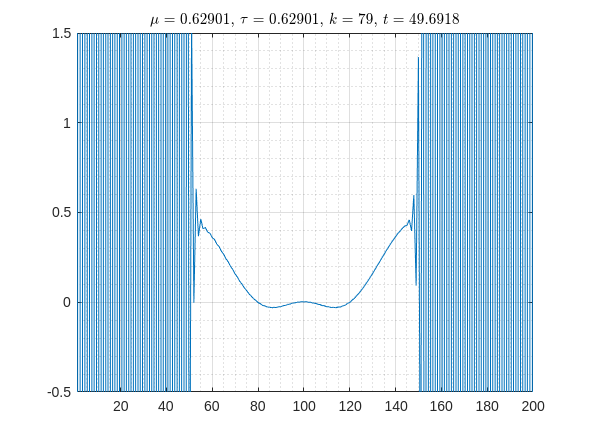

g = g1';

figure;
hold on, box on, grid on;

Pl = plot(x,g);
grid(gca, 'minor');
ylim([-0.5 1.5]);
xlim([1, 200]);
Tl = title('','Interpreter','latex');

for i = 1:numel(mu)
    a = [1-2*mu(i) mu(i) zeros(1,nx-2)];
    A = toeplitz(a,a);
    A(1) = 1-mu(i);
    A(end) = 1-mu(i);
    
    u = A^nT(i) * g;
    
    Pl.YData = u;
    Tl.String = sprintf('$\\mu = %g$, $\\tau = %g$, $k = %d$, $t = %g$',mu(i),dt(i),nT(i),nT(i)*dt(i));
    drawnow
end